dt = datetime("now");

dt = datetime
   12-Feb-2025 21:08:38


dt.Format = 'yyyyMMddHHmm';
outputfile = 'generate_grayscale_matrices_output/output_log_' + string(dt) + '.txt'

outputfile = "generate_grayscale_matrices_output/output_log_202502122108.txt"


diary(outputfile); % Start logging to a file
diary on; % Enable logging

testing


% To try to formulate a solution that allows each row of the CCM have
% unique components (a11, a12, a13 are unique instead of identical) we
% eliminate using identical scalar value rows (the patch method) that
% correspond to R1 R2 R3 (different R values of each patch.

% New method has 3 different scalar values map to the same R value in each
% row. This is done by setting an R value (R1=50, etc), and then
% caluclating any scalar value with that R value (online calculator) so the 
% G, B values are arbitrary.

% Therefore, we need 3 grayscale matrices to calculate each row of CCM
% coefficients.
%   [ s11 s12 s13 ]   [ a11 ]     [ R1 ]
%   [ s21 s22 s23 ] * [ a12 ]  =  [ R2 ]
%   [ s31 s32 s33 ]   [ a13 ]     [ R3 ]

b_redMatrix =   [40 20 10]';
b_greenMatrix = [40 20 10]';
b_blueMatrix =  [40 20 10]';

disp('b_redMatrix: ');

b_redMatrix: 


disp(b_redMatrix);

    40
    20
    10



disp('b_greenMatrix: ');

b_greenMatrix: 


disp(b_greenMatrix);

    40
    20
    10



disp('b_blueMatrix: ');

b_blueMatrix: 


disp(b_blueMatrix);

    40
    20
    10




S_grayscaleMatrix_red = generate_grayscale_matrix(b_redMatrix, 'r');

S_grayscaleMatrix_red =    86.4720   57.9640  111.7570
  158.4510  125.1940   96.5210
  164.8240  133.1970   92.7840


S_grayscaleMatrix_green = generate_grayscale_matrix(b_greenMatrix, 'g');

S_grayscaleMatrix_green =    64.8920   40.8690   58.5080
   71.1670   85.3680   61.3890
   20.1870   65.2730   60.7920


S_grayscaleMatrix_blue = generate_grayscale_matrix(b_blueMatrix, 'b');

S_grayscaleMatrix_blue =   204.2660   93.9450  104.2050
  125.1770   49.0730   55.6180
  113.2860  167.6110  182.0750



disp('S_grayscaleMatrix_red: ');

S_grayscaleMatrix_red: 


disp(S_grayscaleMatrix_red);

   86.4720   57.9640  111.7570
  158.4510  125.1940   96.5210
  164.8240  133.1970   92.7840



disp('S_grayscaleMatrix_green: ');

S_grayscaleMatrix_green: 


disp(S_grayscaleMatrix_green);

   64.8920   40.8690   58.5080
   71.1670   85.3680   61.3890
   20.1870   65.2730   60.7920



disp('S_grayscaleMatrix_blue: ');

S_grayscaleMatrix_blue: 


disp(S_grayscaleMatrix_blue);

  204.2660   93.9450  104.2050
  125.1770   49.0730   55.6180
  113.2860  167.6110  182.0750




c_redMatrix = S_grayscaleMatrix_red\b_redMatrix;

c_redMatrix =     3.7033
   -4.3226
   -0.2656


% c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)
c_greenMatrix = S_grayscaleMatrix_green\b_greenMatrix;

c_greenMatrix =     0.4043
   -0.5464
    0.6169


c_blueMatrix = S_grayscaleMatrix_blue\b_blueMatrix;

c_blueMatrix =     0.3359
    6.3394
   -5.9899



colorCorrectionMatrix = [
    c_redMatrix'; % Red channel mapping
    c_greenMatrix'; % Green channel mapping
    c_blueMatrix'; % Blue channel mapping
    ];

colorCorrectionMatrix =     3.7033   -4.3226   -0.2656
    0.4043   -0.5464    0.6169
    0.3359    6.3394   -5.9899



disp('calculated color correction matrix: ');

calculated color correction matrix: 


disp(colorCorrectionMatrix);

    3.7033   -4.3226   -0.2656
    0.4043   -0.5464    0.6169
    0.3359    6.3394   -5.9899



colorCorrectionMatrix =     3.7033   -4.3226   -0.2656
    0.4043   -0.5464    0.6169
    0.3359    6.3394   -5.9899


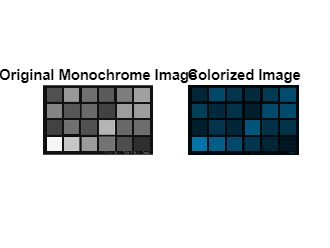

dt = datetime
   12-Feb-2025 21:02:15


filename = "colorized_images/colorized_image_20250212210267.png"

colorized image saved to colorized_images/colorized_image_20250212210267.png



returned_img = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix);

diary off;

functions definitions start

function gray_matrix = generate_grayscale_matrix(b_vector, color)

    % initialize 3x3 mat
    gray_matrix = zeros(3, 3);
    
    % iterate over matrix rows
    for row = 1:3
        % get fixed color channel value for this row
        val = b_vector(row);
        % iterate over columns
        for col = 1:3
            gray_matrix(row, col) = calc_random_gray(val, color);
        end
    end
end

% calculate scalar given one of the component values 
% e.g. if value is a num, and color=='r' then calc gray using (R=value, G=random1, B=random2)
function scalar = calc_random_gray(value, color)  

    % calc random1 and random2 between 0-255
    random1 = randi([0, 255]);
    random2 = randi([0, 255]);

    % calc weighted sum with given color value
    switch lower(color)
        case 'r'
            scalar = 0.299*value + 0.587*random1 + 0.114*random2;
        case 'g'
            scalar = 0.299*random1 + 0.587*value + 0.114*random2;
        case 'b'
            scalar = 0.299*random1 + 0.587*random2 + 0.114*value;
    end
end

function rgbImage = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)
% Read the monochrome image.
initial_rgbImage = imread('images/Reflective-color-chart-reference-COLOR.png', 'png');
grayImage = rgb2gray(initial_rgbImage);

% Define a color correction matrix for RGB color mapping.
% Simple example below.
colorCorrectionMatrix = [
    c_redMatrix'; % Red channel mapping
    c_greenMatrix'; % Green channel mapping
    c_blueMatrix'; % Blue channel mapping
    ]

% Get image dimensions.
[rows, cols] = size(grayImage);

% Initialize RGB image matrix.
% rgbImage = zeros(rows, cols, 3);
rgbImage = initial_rgbImage; % Hijacks format used by imread.

% Apply color correction by looping over each pixel.
for i = 1:rows
    for j = 1:cols
        % Get grayscale value of current pixel.
        grayValue = double(grayImage(i, j)); 

        % Apply color correction matrix to map grayscale value to RGB
        % values.
        rgbValue = colorCorrectionMatrix * [grayValue; grayValue; grayValue];
        
        % Store RBG values in the output image matrix.
        rgbImage(i, j, :) = uint8(rgbValue); % ':' is the rgb vector
    end
end

% Display the original monochrome image and the transformed color image.
figure;
subplot(1, 2, 1);
imshow(grayImage);
title('Original Monochrome Image');
% rgbImage

subplot(1, 2, 2);
imshow(rgbImage);
title('Colorized Image');

% Save the colorized image to a new file.
dt = datetime("now");
dt.Format = 'yyyyMMddHHmmSS';
filename = 'colorized_images/colorized_image_' + string(dt) + '.png';
imwrite(rgbImage, filename);

fprintf('colorized image saved to %s\n', filename);

end

function definitions end